# Sliding Mode Control Design for a Robotic Manipulator

This example shows how to design a controller for a robotic manipulator with two actuated joints using sliding mode control (SMC). SMC is useful for systems that require robustness against disturbances and model uncertainties. Using SMC, you can obtain high-precision tracking of desired trajectories even in the presence of external disturbances and parameter variations. For more information on SMC, see [Sliding Mode Control Design for a Mass-Spring-Damper System](docid:slcontrol_ug#mw_ba00b52b-d5d4-4855-a4f2-92b4f7fc2d2d).

## Dynamics of Robotic Manipulator

Consider the dynamics of a two-jointed robotic manipulator governed by the following dynamic equation.


$$$$ M(q) \ddot{q} + C(q, \dot{q}) \dot{q} + G(q) + F(\dot{q}) = \tau + \tau_d $$$$


Here:

- $q$, $\dot{q}$, and $\ddot{q}$ are 2-by-1 vectors representing the joint angles, velocities, and accelerations, respectively.

- The control input $\tau$ is 2-by-1 torque vector applied to the joints.

- The inertia matrix $M\left(q\right)$, Coriolis matrix $C\left(q,\dot{q} \right)$, gravity vector $G\left(q\right)$, and friction vector $F\left(\dot{q} \right)$ encapsulate the dynamics of the manipulator

- $\tau_d$ represents the disturbance torques affecting the system.

To facilitate control design, define the state variables $x_1 =q$ and $x_2 =\dot{q}$, and control input $u=\tau$. Then define the more compact state-space representation of the system.


$$$$
\left\lbrace
\begin{array}{l}
\dot{x}_1 = x_2 \\
\dot{x}_2 = f(x) + g(x) \cdot u(t)
\end{array}
\right.
$$$$


The state vector $x\left(t\right)$ is given by:

$x\left(t\right)=\left\lbrack \begin{array}{c}
q\\
\dot{\;q} 
\end{array}\right\rbrack$, where $q=\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 
\end{array}\right\rbrack$

Here, $f\left(x,t\right)={M\left(q\right)}^{-1} \left\lbrack \tau_d -C\left(q,\dot{q} \right)\dot{\;q} -G\left(q\right)-F\left(\dot{\;q} \right)\right\rbrack$ and $g\left(x,t\right)={M\left(q\right)}^{-1}$

The robot manipulator dynamics are implemented in the `robotStateFcn` helper function. This function generates the state derivatives with respect to time based on the current state vector $x$, the control input vector $u$, and a vector of model parameters. For this example, assume that the friction model, $F\left(\dot{q} \right)$ is negligible and not used in calculations.

For this example, define the following parameters of the robot manipulator.

- M1 and M2 — Masses of the first and second links (kg)

- L1 and L2 — Lengths of the first and second link (m)

- J1 and J2 — Moments of inertia of the first and second link (kgm^2)

M1 = 0.5;
M2 = 1.5;
L1 = 1;
L2 = 0.8;
J1 = 5;
J2 = 5;

## Reference Trajectory for Robotic Manipulator

In this example, the reference trajectories for the two actuated joints of the robotic manipulator are described by time-varying exponential functions. 


$$\theta_{1,2} =a_{1,2} +b_{1,2} e^{d_{1,2} t} +c_{1,2} e^{e_{1,2} t}$$


The reference trajectory primarily targets the set points $a_{1,2}$, with additional terms ensuring a smooth transition from the initial position to these set points. The differentiation of these functions is essential for producing consistent velocity and acceleration profiles, contributing to the manipulators stability and precise movement. This characteristic also facilitates the use of control algorithms that require continuous and differentiable set points.

For this example, set the parameters for the reference trajectories of both joints. These parameters define the shape and behavior of the trajectory functions over time.

[a1,b1,c1,d1,e1] = deal(1,-1,0.25,-1,-4);
[a2,b2,c2,d2,e2] = deal(1,1,-0.3,-1,-3);

Plot the reference trajectories for both joints to visualize the target positions over the specified time interval. 

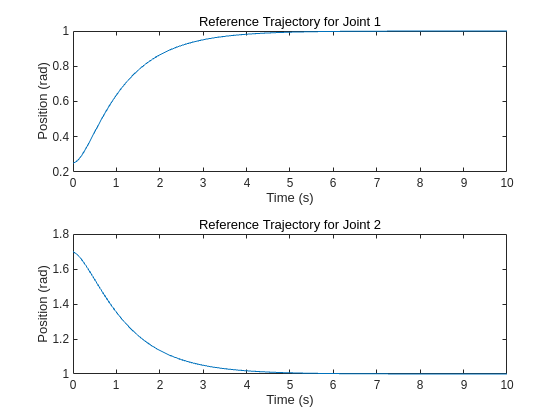

qref = @(time,a,b,c,d,e) a + b*exp(d*time) + c*exp(e*time);
time = linspace(0,10);

figure
tiledlayout(2,1)

nexttile
plot(time,qref(time,a1,b1,c1,d1,e1))
title("Reference Trajectory for Joint 1")
ylabel("Position (rad)")
xlabel("Time (s)")

nexttile
plot(time,qref(time,a2,b2,c2,d2,e2))
title("Reference Trajectory for Joint 2")
ylabel("Position (rad)")
xlabel("Time (s)")

## Design Sliding Mode Controller

SMC is a robust control strategy that forces the system state to converge to a predefined sliding surface and maintain this condition thereafter. This objective is achieved through the application of a discontinuous control action that switches depending on the system position relative to the sliding surface.

In this example, the SMC control law used is:


$$u=\;\frac{1}{g}\left(\eta \;\textrm{sign}\left(s\right)+\textrm{ks}+c\dot{e} +{\ddot{x} }_d -f+\textrm{Dsign}\left(s\right)\right)$$


The control depends on the following parameters.

- $e$: Tracking error defined  $e=q_d -q$. 

- $s$: Sliding mode function defined as $s\left(t\right)=\textrm{ce}\left(t\right)+\dot{\;e} \left(t\right)$.

- $\eta$: Amplitude of the discontinuous control action, enhances robustness against disturbances.

- $k$: Proportional gain in the continuous part of the control law, reduces steady-state error and improves response time.

- $c$: Coefficient in the sliding surface, affects the rate of convergence to the sliding surface.

- $D:$ Upper bound of the disturbance.

The terms $f$and $g$ are dependent of the robot manipulator parameters. In real-world scenarios, you might not know these parameters exactly and only have estimated values available.


$$f\left(x,t\right)={\hat{M} \left(q\right)}^{-1} \left\lbrack \tau_d -\hat{C} \left(q,\dot{q} \right)\dot{\;q} -\hat{G} \left(q\right)-\hat{F} \left(\dot{\;q} \right)\right\rbrack$$


 
$$g\left(x,t\right)={\hat{M} \left(q\right)}^{-1}$$


Here, the manipulator inertia matrix $\hat{M} \left(q\right)$, Coriolis matrix $\hat{C} \left(q,\dot{q} \right)$, friction vector $\hat{F} \left(\dot{q} \right)$ and gravity vector $\hat{G} \left(q\right)$ are estimated values. 

To reduce chattering in the control signal, you can replace the `sign` with the following saturation function.


$$\textrm{sat}\left(\frac{s}{\phi }\right)=\left\lbrace \begin{array}{ll}
1 & s\ge \phi \\
\frac{s}{\phi } & -\phi <s<\phi \\
-1 & s<\phi 
\end{array}\right.$$


This approximation of the signum function requires the boundary layer thickness, $\phi$, to be positive.

For this example, define the following SMC controller parameters.

eta = [1; 3];  % Amplitude of discontinuous control action
K = [2; 1];    % Proportional gain
C = [5; 5];    % Sliding surface coefficient
D = [10;5];         % Disturbance estimate
Phi = 0.01;    % Boundary layer thickness
delta = 0.01;

## Closed-Loop Simulation Using SMC Controller

To evaluate the performance of the designed SMC controller, simulate the robotic manipulator in Simulink®. The simulation tests the controller reference tracking under conditions of both known and uncertain parameters.

Open the model.

mdl = "robotManipulatorModel";
open_system(mdl)

'RTWTesting' 기능은 이미 등록되었습니다.

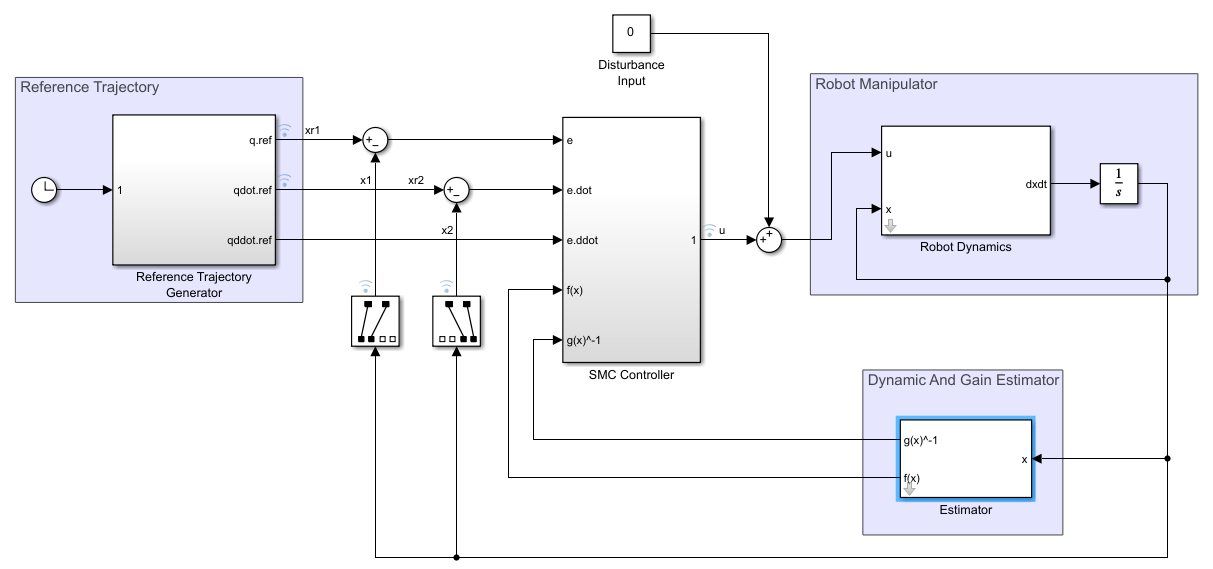

Simulate the system starting from any initial position with zero velocity using the signum function.

Define the initial state of the robotic manipulator.

x0 = [0;0;0;0];

Choose the variant of the control strategy. In this case, use the `sign` function variant for the SMC controller.

variantPath = "robotManipulatorModel/SMC Controller/Variant Subsystem";
set_param(variantPath,"OverrideUsingVariant","sign");

Set the robot dynamics parameters for the simulation within the Estimator subsystem, assuming that the robot parameters are known and unaffected by any external disturbances.

[Md1,Md2,Ld1,Ld2,Jd1,Jd2] = deal(M1,M2,L1,L2,J1,J2);

Simulate the model.

simout = sim(mdl);

Post process the simulation results for plotting.

[sim1, ref] = postProcessSimResults(simout,C);

Simulate the system with the same initial conditions but with a parameter mismatch between the robot and the Estimator subsystem. Doing so tests the robustness of the SMC controller against model uncertainties.

Md1 = 0.1;
Md2 = 1.0;
Ld1 = 1;
Ld2 = 0.8;
Jd1 = 4;
Jd2 = 6;

simout = sim(mdl);
sim2 = postProcessSimResults(simout,C);

Plot the simulation results.

figure
stackedplot(ref,sim1,sim2, ...
    ["q1","q2","qdot1","qdot2"], ...
    Title="State Trajectories");

The SMC controller is still capable of tracking the reference trajectory even after adjusting the parameters. 

Visualize the controller performance by plotting the control inputs and the sliding mode function.

figure
stackedplot(sim1,sim2, ...
    {"Tau1","S1","Tau2","S2"}, ...
    Title="Control Inputs and Slide Mode Function Plots");

## Reduce Control Input Chattering

Due to the use of the signum function in the SMC controller, the control input exhibits chattering. One common practice to reduce chattering is to use the saturation function instead of the sign function.

% switch the controller to use saturation function
variantPath = "robotManipulatorModel/SMC Controller/Variant Subsystem";
set_param(variantPath,"OverrideUsingVariant","saturation");

Assign known dynamic parameters to the controller for the first simulation run.

[Md1,Md2,Ld1,Ld2,Jd1,Jd2] = deal(M1,M2,L1,L2,J1,J2);

Execute the simulation with the saturation function in place.

simout = sim(mdl);
[sim3, ref] = postProcessSimResults(simout,C);

Specify the mismatched parameter values and simulate the robot.

Md1 = 0.1;
Md2 = 1.0;
Ld1 = 1;
Ld2 = 0.8;
Jd1 = 4;
Jd2 = 6;

simout = sim(mdl);
sim4 = postProcessSimResults(simout,C);

Plot the state trajectories to compare the performance of the controller with the saturation function against the reference trajectories and previous results.

figure
stackedplot(ref,sim1,sim2,sim3,sim4, ...
    ["q1","q2","qdot1","qdot2"], ...
    Title="State Trajectories")

Plot the control inputs and sliding mode function.

figure
stackedplot(sim3,sim4, ...
    {"Tau1","S1","Tau2","S2"}, ...
    Title="Control Inputs and Slide Mode Function Plots");

When you use the saturation function in the control law, chattering is significantly reduced in the control input.

Another way to reduce chattering is to use the relay function instead of the sign function.  You can try it out by selecting "relay" in the variant subsystem in the Simulink model.

*Copyright 2023-2024 The MathWorks, Inc.*